# **Analysis 3 C134: Live-fixed cell analysis**

HeLa ND-cdt1 overexpression with GMNN  overexpression

**Testing for:**

-Reverify that ND-Cdt1 inhibits dna replication in HeLa

-Does GMNN counteract EdU inhib

-Does GMNN(82-133) counteract EdU inhib

-Does GMNN(82-133) allow for licensing?

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'YFP',[2 5],2:4,1:4,[0 0 0]; %1    
        'NR52',[2 5],5:7,1:4,[0 0 0]; %1    
        'NR53',[2 5],8:10,1:4,[0 0 0]; %1    
    };


load([dataDir 'C134_data.mat'],'S');
% S = loadData_C134(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;


**G1 cells**

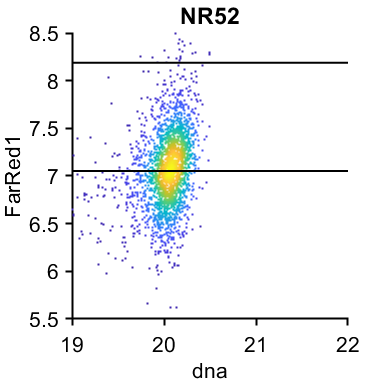

cond=2;

xval = 'dna';
yval = 'FarRed1';

condition = cond;
xdata = log2(S(condition).(xval));
ydata =  log2(S(condition).(yval));

ally = ydata;
inds = log2(S(condition).dna) < 20.5 & S(condition).apcNuc(:,end) < 20 & S(condition).FarRed1 < 2^8.5;
xdata = xdata(inds);
ydata = ydata(inds);

figure('units','inches','pos', [0 0 4 4])
hold on
dscatter(xdata,ydata);
xlim([19 22])
% ylim([5 13])
edu_thresh = prctile(ydata,[50 99]);
hline(edu_thresh,'k')
ylabel(yval);
xlabel(xval);
title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');

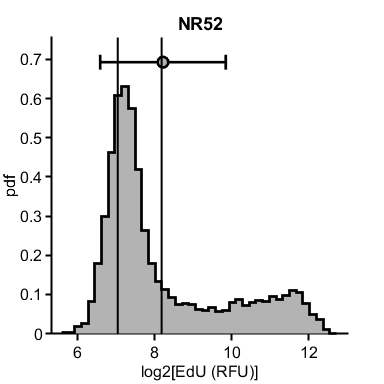


figure('units','inches','pos', [0 0 4 4])
hold on
nhist(ally,'pdf');
% xlim([19 22])
% ylim([5 13])
vline(edu_thresh,'k')
% ylabel(yval);
xlabel('log2[EdU (RFU)]');
title(conditions{condition,1});
axis square

print_pdf([pwd() '\Figs\eduhist.pdf'])

**PCNA vs EdU levels early S cells**

ans = 1269

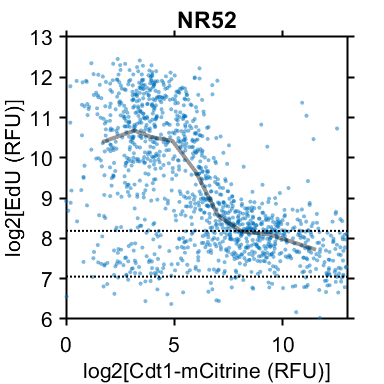

conds=[2];

xval = 'YFP1';
yval = 'FarRed1';


for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).sigNuc(:,end));
    ydata =  (S(condition).(yval));
    
    xdata(xdata<.01) = .01;
    ydata(ydata<.01) = .01;
    
    xdata = log2(xdata);
    ydata = log2(ydata);
    
    inds = log2(S(condition).dna) < 20.5 & S(condition).apcNuc(:,end) > 64 ...
        &  xdata < 13 & xdata > 0;

    xdata = xdata(inds);
    ydata = ydata(inds);
    length(xdata)
%     edges = linspace(2,13,15);
        edges = prctile(xdata,linspace(1,99,10));
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
        'Edges',edges);
    midpoints = edges;
    midpoints = (midpoints(1:end-1) + midpoints(2:end))/2 ;
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    colormap('viridis')
    %     dscatter(xdata,ydata,'MSIZE',10,'MARKER','o');
    scatter(xdata,ydata,10,'filled','MarkerFaceAlpha',.5)
    patchline(midpoints(binData(1).numCells > 10),binData(1).median(binData(1).numCells > 10),'LineWidth',3,'EdgeAlpha',.4)
    xlim([0 13])
    ylim([6 13])
    %     vline(log2(gate.RFP_G1(2)),'k');
    hline(edu_thresh,'k:');
    axis square
    ylabel('log2[EdU (RFU)]');
    xlabel('log2[Cdt1-mCitrine (RFU)]');
    %     set(gca,'FontSize',8)
    box on
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    print_pdf([pwd() '\Figs\Cdt1vsEdU_' num2str(i) '.pdf'])
    
       
end